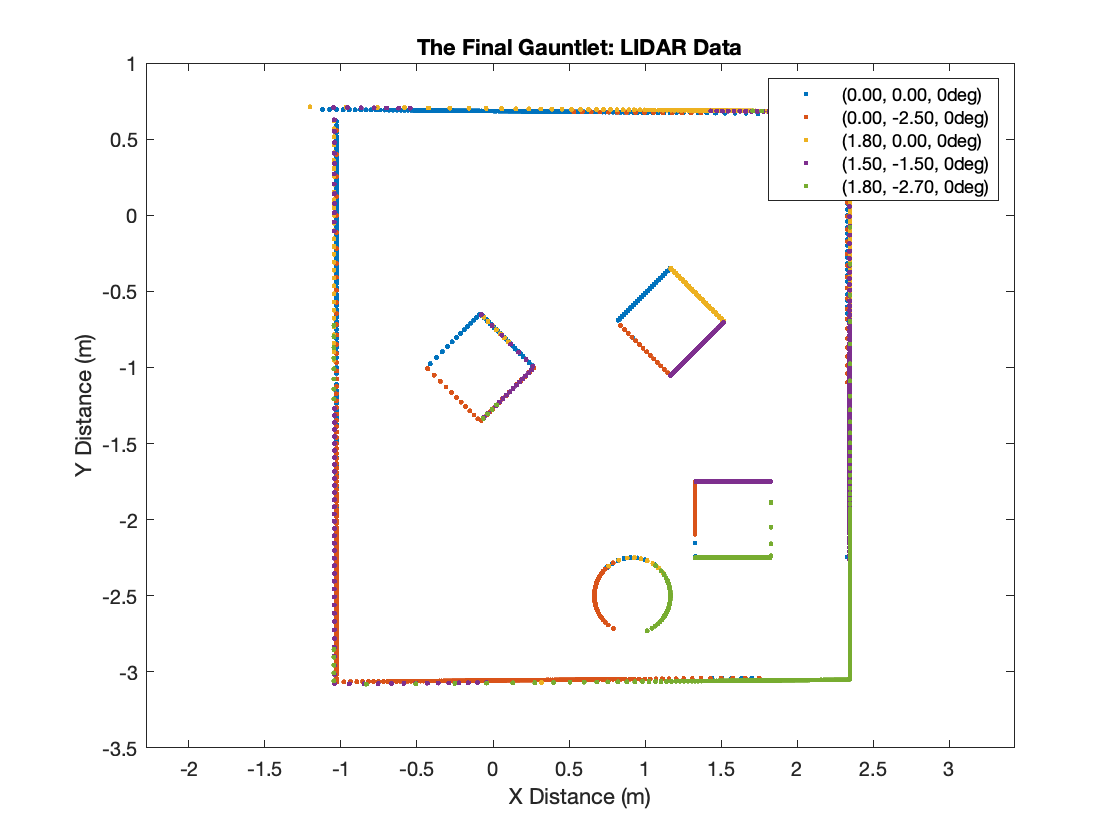

load('scans/lidar2.mat', 'lidar_results', 'lidar_positions');
% lidar.mat has a lidar matrix which is n x 2 x m, where each (:, :, m) is
% one scan in the form of [r, theta], where r and theta are column vectors.
% It also has a 3 x m matrix of column vectors of the format [x, y, phi],
% representing the position and orientation of the Neato when each scan was
% taken

clf;

for i=1:size(lidar_results, 3)
    r_G = to_global(lidar_results(:, 1, i), lidar_results(:, 2, i), lidar_positions(i, 1:2), lidar_positions(i, 3));
    label = sprintf("(%1.2f, %1.2f, %1.0fdeg)", lidar_positions(i, 1), lidar_positions(i, 2), lidar_positions(i, 3));
    plot(r_G(:, 1), r_G(:, 2), '.', 'DisplayName', label); hold on;
end

legend show;
title("The Final Gauntlet: LIDAR Data");
xlabel("X Distance (m)");
ylabel("Y Distance (m)");
xlim([-1.5, 3]);
ylim([-3.5, 1]);

axis equal;

hold off;

## Potential Field

syms X Y;

wall = ...
    log(sqrt((Y + 3.37) .^ 2)) + ...
    log(sqrt((Y - 1.00) .^ 2)) + ...
    log(sqrt((X + 1.50) .^ 2)) + ...
    log(sqrt((X - 2.50) .^ 2));

obstacle_info = [
    -0.25, -1.0, pi/4, 0.5;
     1.41, -2.0,    0, 0.5;
     1.00, -0.7, pi/4, 0.5
];

bucket_x = 0.75;
bucket_y = -2.5;
bucket_r = 0.25;

obstacles = 0;

corners = [];

for i=1:size(obstacle_info, 1)
    obstacles = obstacles + ...
        log(sqrt((X - obstacle_info(i, 1)) .^ 2 + (Y - obstacle_info(i, 2)) .^ 2));
    
    corners(:, :, i) = squareToLines(obstacle_info(i, 1), obstacle_info(i, 2), obstacle_info(i, 3), obstacle_info(i, 4));
    
    for j=1:size(corners, 1)
        obstacles = obstacles + ...
            log(sqrt((X - corners(j, 1, i)) .^ 2 + (Y - corners(j, 2, i)) .^ 2));
    end
end

Z = (0.02 * obstacles) ...
    + (0.04 * wall) ...
    - (0.6 * log(sqrt((X - bucket_x) .^ 2 + (Y - bucket_y) .^ 2)));

potential_field = Z

$$potential\_field = 0.0200\,\log\left(\sqrt{{\left(X-0.6464\right)}^{2}+{\left(Y+0.7000\right)}^{2}}\right)-0.6000\,\log\left(\sqrt{{\left(Y+2.5000\right)}^{2}+{\left(X-0.7500\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1.3536\right)}^{2}+{\left(Y+0.7000\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+2.2500\right)}^{2}+{\left(X-1.6600\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1.1600\right)}^{2}+{\left(Y+1.7500\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(X-2.5000\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1.6600\right)}^{2}+{\left(Y+1.7500\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(X+1.5000\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(Y+3.3700\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+1\right)}^{2}+{\left(X+0.2500\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1\right)}^{2}+{\left(Y+1.0536\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+1\right)}^{2}+{\left(X+0.6036\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1\right)}^{2}+{\left(Y+0.3464\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X-1\right)}^{2}+{\left(Y+0.7000\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+2\right)}^{2}+{\left(X-1.4100\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+1\right)}^{2}+{\left(X-0.1036\right)}^{2}}\right)+0.0400\,\log\left(\sqrt{{\left(Y-1\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(Y+2.2500\right)}^{2}+{\left(X-1.1600\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X+0.2500\right)}^{2}+{\left(Y+0.6464\right)}^{2}}\right)+0.0200\,\log\left(\sqrt{{\left(X+0.2500\right)}^{2}+{\left(Y+1.3536\right)}^{2}}\right)$$

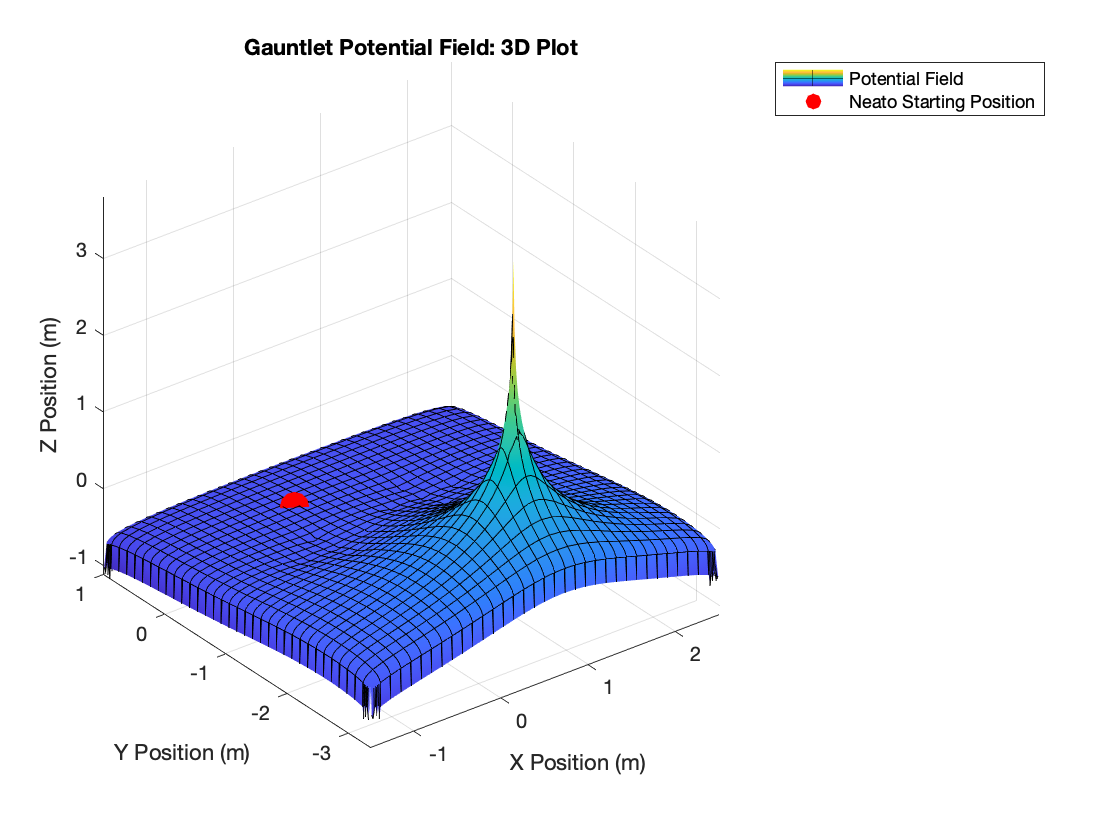


f = matlabFunction(Z);
grad = matlabFunction(gradient(Z));

figure(2); clf;

fsurf(f, [-1.5, 2.5, -3.37, 1]); hold on;
plot3(0, 0, f(0, 0), 'r.', 'MarkerSize', 50);
xlim([-1.5, 2.5]); ylim([-3.37, 1]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");
legend("Potential Field", "Neato Starting Position");
title("Gauntlet Potential Field: 3D Plot");
hold off;

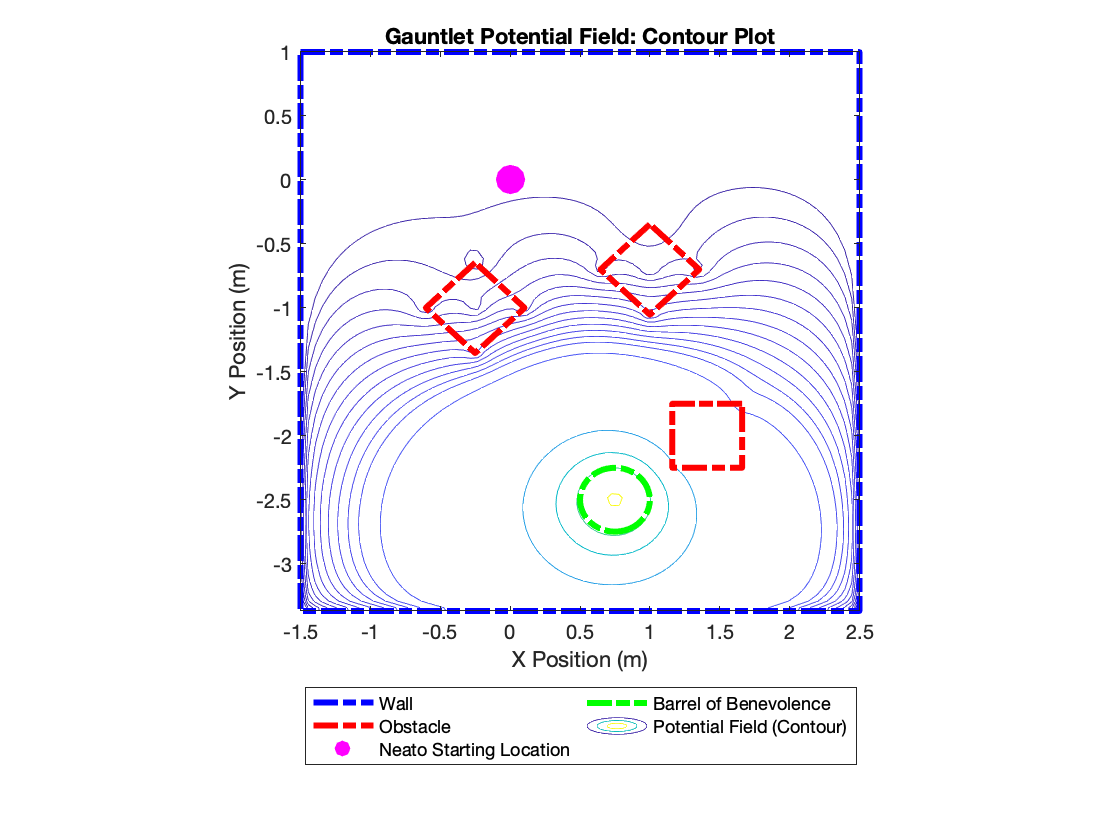


figure(3); clf;

[x, y] = meshgrid(linspace(-2, 3), linspace(-4, 1));

z = f(x, y);

[~, pcontour] = contour(x, y, z, [0, -0.05:-0.025:-.35, .5, .75, 1, 2, 5]);

xlim([-1.5, 2.5]); ylim([-3.37, 1]); xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");

axis square; hold on;

wallpts = [
    -1.5, 1;
     2.5, 1;
     2.5, -3.37;
    -1.5, -3.37;
    -1.5, 1; % last point repeated to get a closed box
];

pwall = plot(wallpts(:, 1), wallpts(:, 2), 'b-.', 'LineWidth', 3);

for i=1:size(corners, 3)
    pts = [corners(:, :, i); corners(1, :, i)]; % we add the first point again to the end to get a closed box
    pobstacle = plot(pts(:, 1), pts(:, 2), 'r-.', 'LineWidth', 3);
end

pbucket = fimplicit(@(x, y) ((x - bucket_x).^2 + (y - bucket_y).^2 - bucket_r.^2), 'g-.', 'LineWidth', 3);
pneato = plot(0, 0, 'm.', 'MarkerSize', 50);
lgnd = legend([pwall, pobstacle, pneato, pbucket, pcontour], {"Wall", "Obstacle", "Neato Starting Location", "Barrel of Benevolence", "Potential Field (Contour)"});
lgnd.Location = 'southoutside';
lgnd.NumColumns = 2;
title("Gauntlet Potential Field: Contour Plot");

## Gradient Ascent

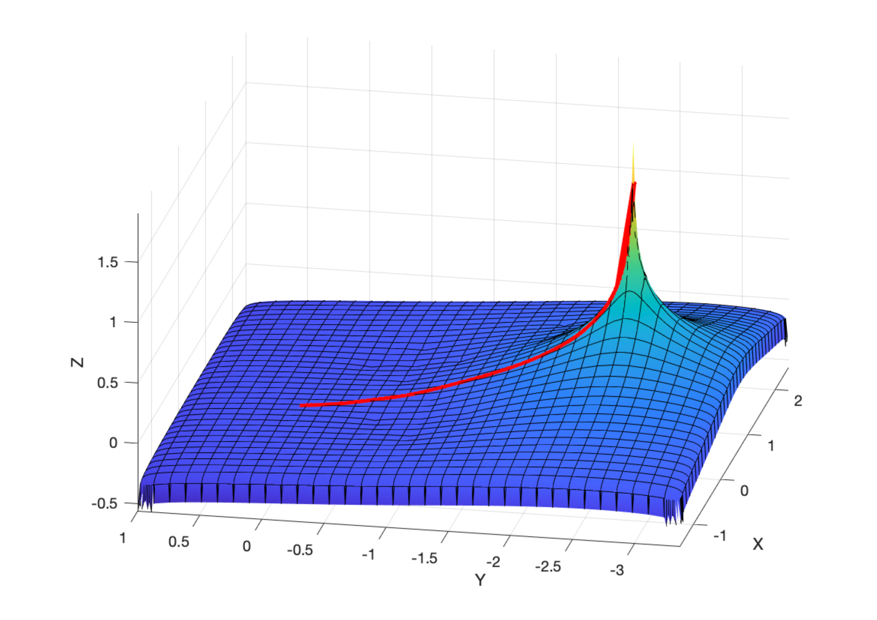

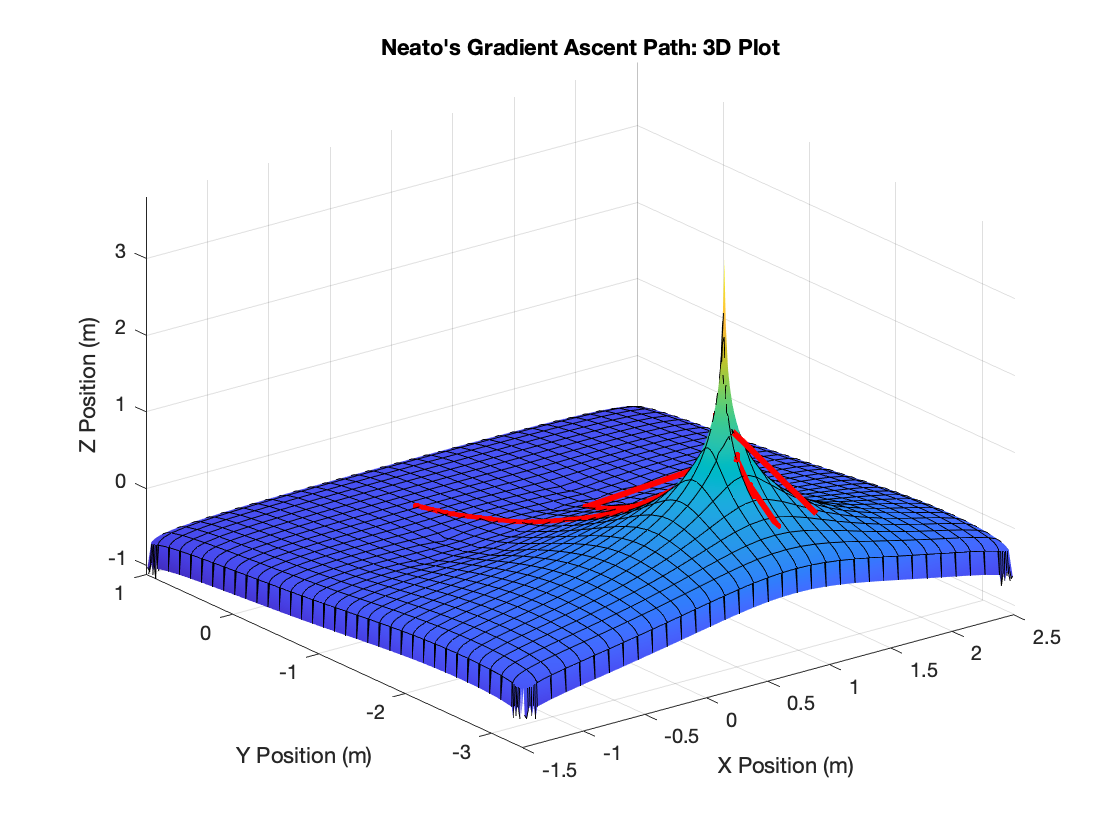

[positions, headings] = gradient_ascent(grad, [0, 0], [1, 0], 1, .9554, .01, 1000); % run gradient ascent



figure(5); clf;
fsurf(f, [-1.5, 2.5, -3.37, 1]); hold on;
plot3(positions(:, 1), positions(:, 2), f(positions(:, 1), positions(:, 2)), 'r.-', 'LineWidth', 3, "MarkerSize", 10);
title("Neato's Gradient Ascent Path: 3D Plot");
xlim([-1.5, 2.5]); ylim([-3.37, 1]);
xlabel("X Position (m)"); ylabel("Y Position (m)"); zlabel("Z Position (m)");

## Generate Commands for Neato

dt = 1; % seconds per timestep
d = 0.235; % wheelbase of the Neato, in meters
ts = (1:length(positions))' .* dt; % generate timesteps

% calculate the linear difference between each position
dp = diff(positions);
dists = vecnorm(dp, 2, 2);

% calculate the angular difference between each position
angles = pi - atan2(positions(:, 2), positions(:, 1));
dangles = diff(angles);

% the linear and angular velocities are the linear and angular distances
% (respectively) divided by time.
ang_vel = dangles ./ dt;
lin_vel = dists ./ dt;

% calculate the left and right wheel velocities
v_l = lin_vel + (ang_vel .* (d / 2));
v_r = lin_vel - (ang_vel .* (d / 2));

% pack those into messages that can be sent to ROS
msgs = [v_l, v_r];


% store the messages, timestamps, and a starting heading and position for
% the neato's script
startPos = [0, 0];
startHead = [1, 0];
save("drivedata.mat", "ts", "msgs", "startHead", "startPos");

## Clean Up Encoder Data

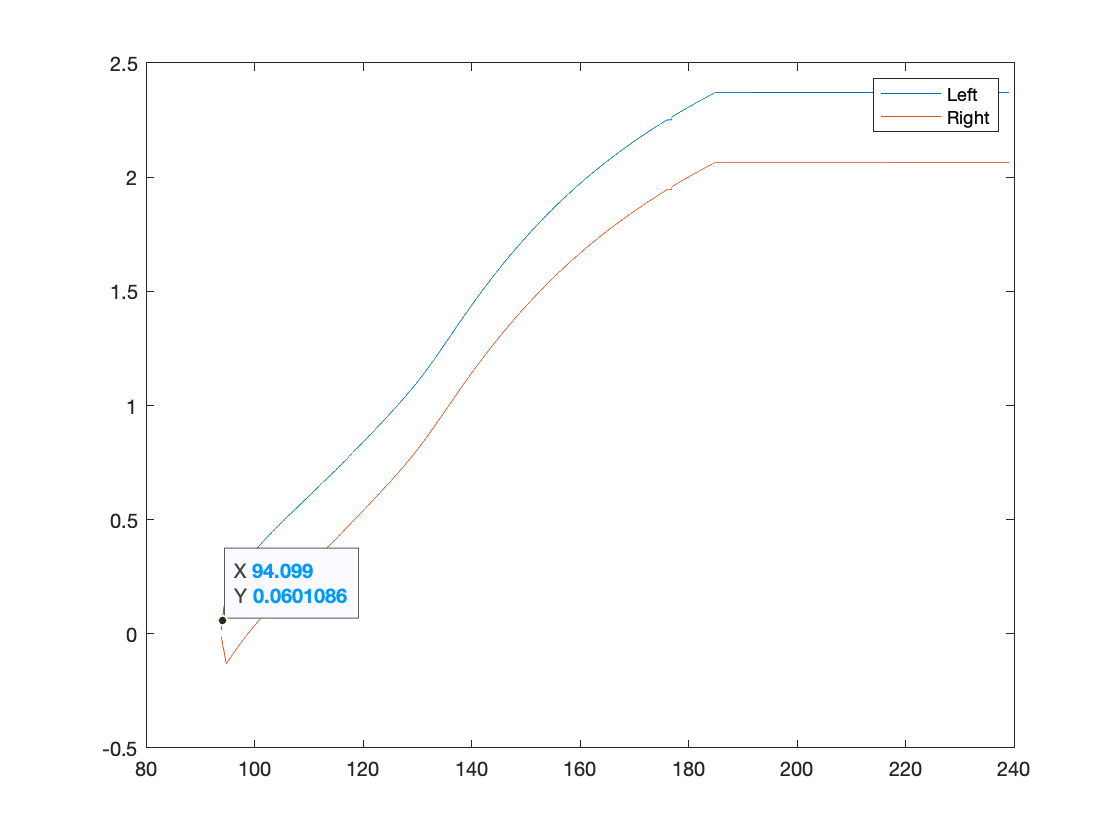

load("encoder_data.mat"); clf;
plot(enc_t, enc_l); hold on;
plot(enc_t, enc_r); hold off;
legend("Left", "Right")


mask = ~isnan(enc_t) & ~isnan(enc_r) & ~isnan(enc_l) & (enc_r > 0 | enc_l > 0);
enc_t = enc_t(mask);
enc_r = enc_r(mask);
enc_l = enc_l(mask);

save("encoder_data.mat", "enc_t", "enc_l", "enc_r")